DFT umschreiben

36 Frequenzen gesucht

beginnt bei Taste d 30 = 146,83 Hz

endet bei 65 = 1108,73 Hz

0,1 Sekunden Refresh-Rate

Amplitude aus Farbe mappen

Farben von Blau bis Rot

Blau, wenn Frequenz keine Amplitude hat / Ruhezustand

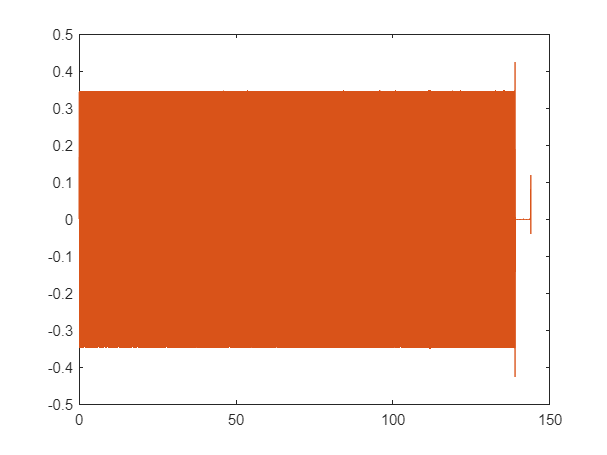

numberOfKeys = 36;
refreshRate = 0.1;
key_min = 30;
key_max = 30 + 36 - 1;

[y, Fs] = audioread("frequenztest.wav");
x = (1:length(y))/Fs;
plot(x, y);

n = Fs * 0.1;
l = floor(length(y) / n);
result = zeros(1, 1:l);

Error using zeros
Size inputs must be scalar.

for i = 0:l
    y_part = y((n * i) + 1: n * (i + 1));
    Y = newDFT(y_part, key_min, key_max);
    l(1, i) = Y;
end

X = newDFT(x_part, key_min, key_max);
%plot(X, )